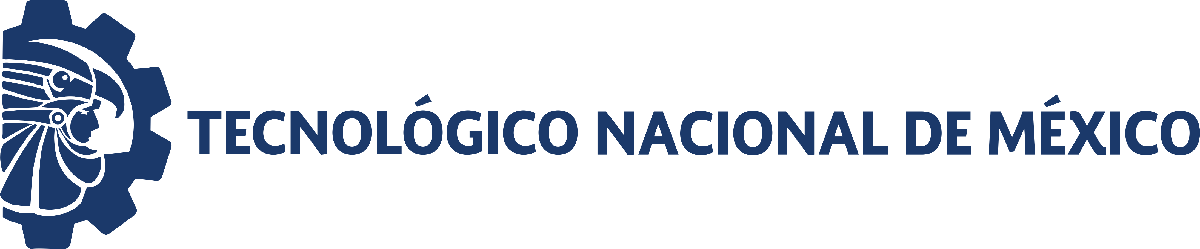                                 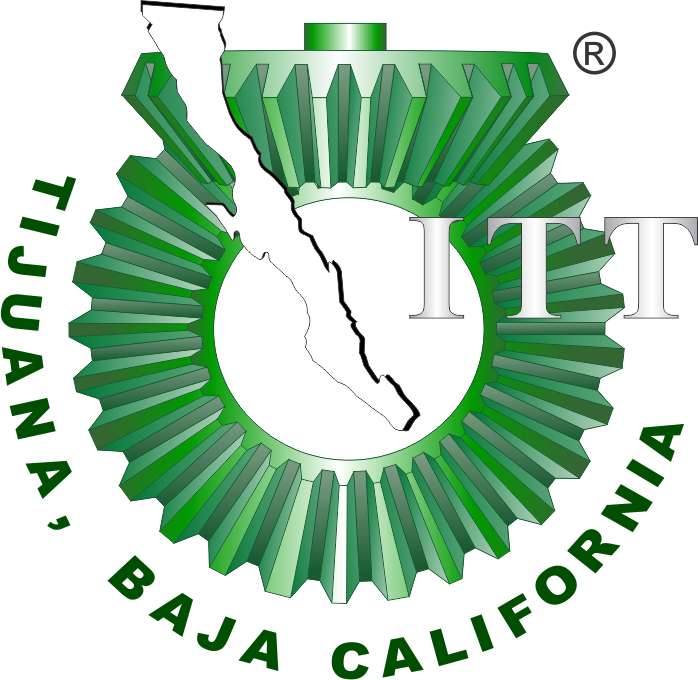

# Práctica tres: Sistema Musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

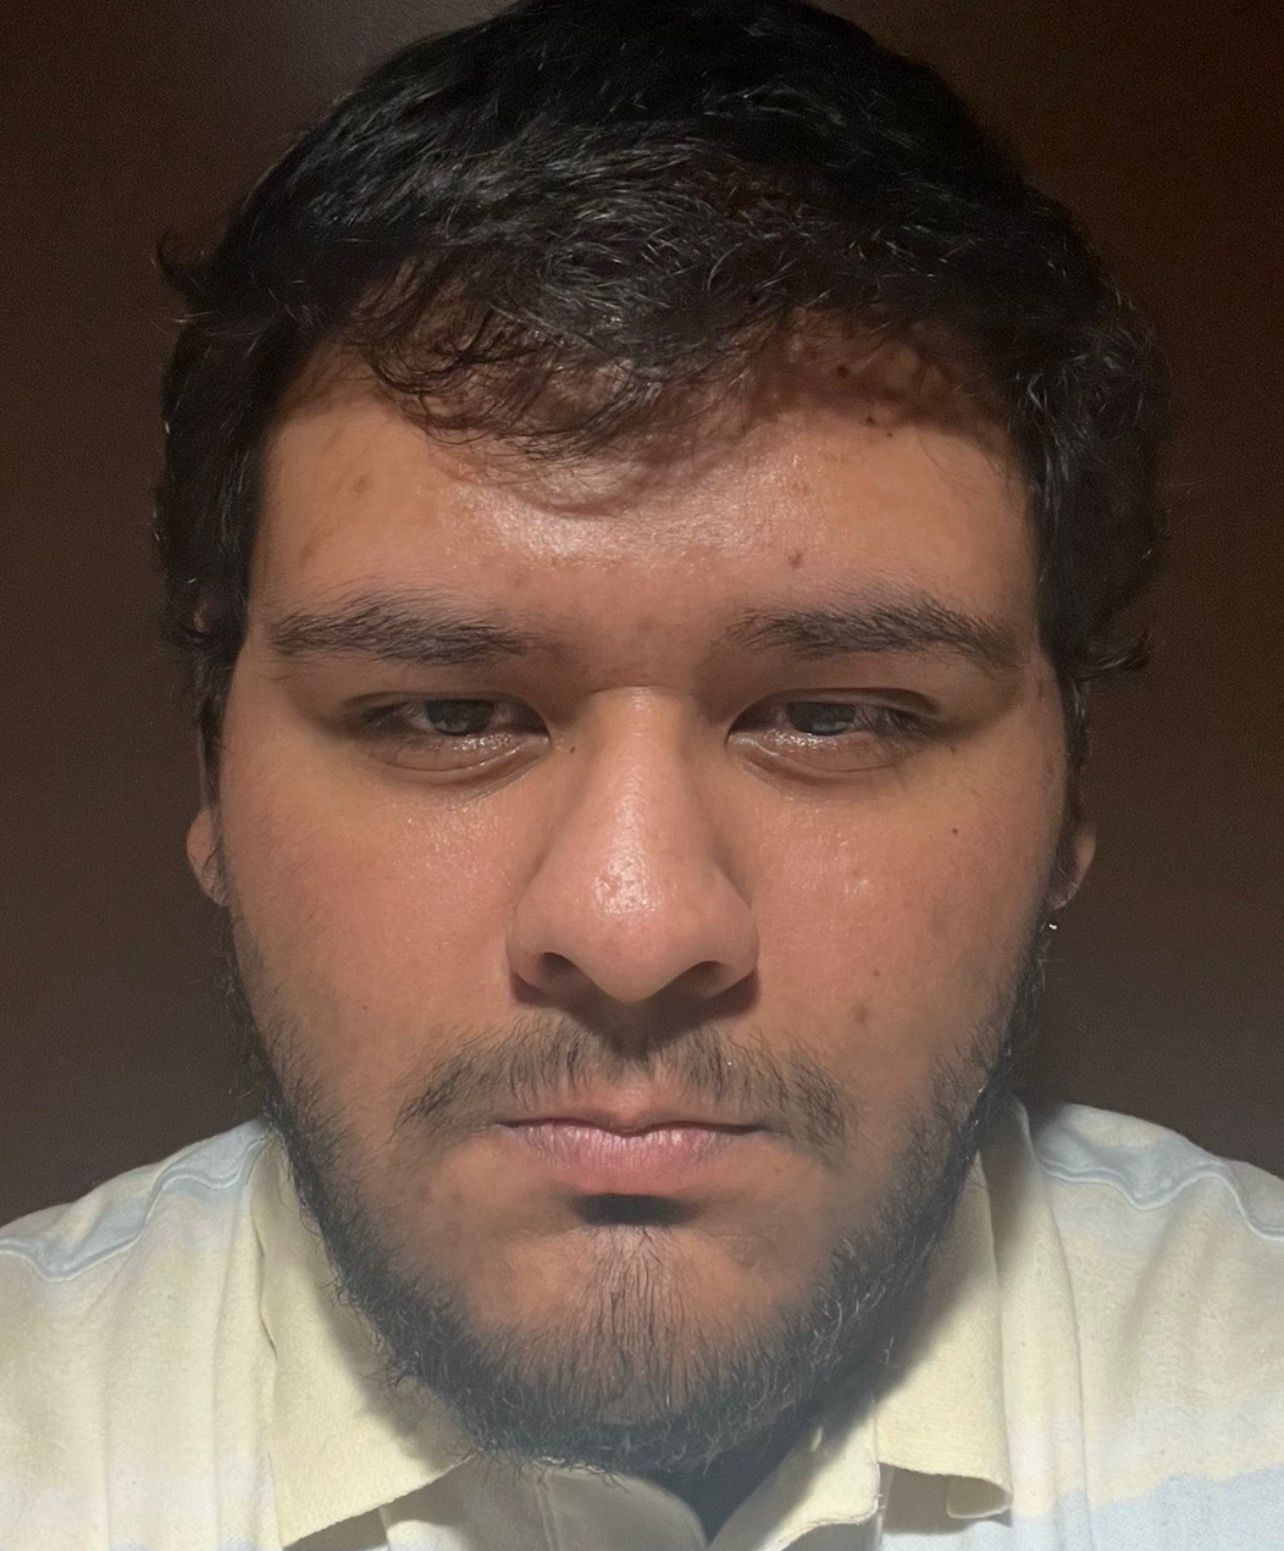

Nombre del alumno: Aaron Raul Rosas Montoya

Número de control: 23210716

Correo institucional: l23210716**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema';
open_system(file);
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim(file,parameters);

## Respuesta del sistema

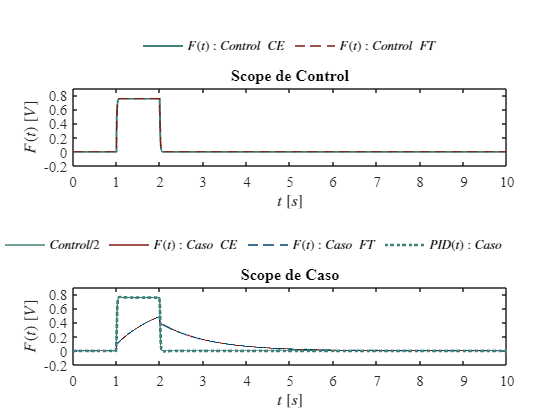

plotsignals(x.t, x.Control, x.Caso, x.PID1)

## Función: Respuestas a las señales

function plotsignals(t, Control, Caso, PID1)

set(figure(), 'Color', 'w')
set(gca, 'Units', 'centimeters', 'Position', [1, 1, 25, 20])

mycolors = [0.25, 0.51, 0.47;
            0.50, 0.10, 0.05;
            0.00, 0.25, 0.40];
colororder(mycolors)

% --- Gráfica 1: Scope de Control ---
subplot(2, 1, 1);
box on; hold on;

P = plot(t, Control, '-', t, Control, '--', 'LineWidth', 1);
set(P(1), 'LineWidth', 1.5)

L = legend('$F(t): Control\ CE$', '$F(t): Control\ FT$');
set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'NorthOutside', ...
       'Box', 'Off', 'Orientation', 'Horizontal');

xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11)
ylabel('$F(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 11)
xlim([0, 10]); xticks(0:1:10);
ylim([-0.2, 0.9]); yticks(-0.2:0.2:0.9);

T = title("Scope de Control");
set(T, 'FontSize', 10);
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)

% --- Gráfica 2: Scope de Caso ---
subplot(2, 1, 2);
box on; hold on;

P = plot(t, Control, '-', t, Caso, '-', t, Caso, '--', t, PID1, ':', 'LineWidth', 1);
set(P(4), 'LineWidth', 2)

L = legend('$Control/2$', '$F(t): Caso\ CE$', '$F(t): Caso\ FT$', '$PID(t): Caso$');
set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'NorthOutside', ...
       'Box', 'Off', 'Orientation', 'Horizontal');

xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11)
ylabel('$F(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 11)
xlim([0, 10]); xticks(0:1:10);
ylim([-0.2, 0.9]); yticks(-0.2:0.2:0.9);

T = title("Scope de Caso");
set(T, 'FontSize', 10);
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)

exportgraphics(gcf, 'musculoesqueletico.pdf', 'ContentType', 'vector')

end